    clc;
    clear;
    close all
    init_val=1;
    rho=2710;
    cd 'F:\Privacy\kntu Uni\MySemesters\Semester 4\Mechatronics\Final Project\Scara\Matlab'
warning('off')

# Mechatronics Final Project

**student: amir saman mirjalili**

**instructor: Dr.Delrobaei**

## **Scara Robot Structure**

scara robot as 4 Dof simple serial robot with a shematic Depicted in figure 1.this robot composed from 4 joints,which are 3 revolute joints and one prismatic.

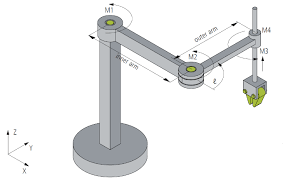

**figure 1: scara robot **

## Drawing Application

in a drawing application we have a given trajectory for the end effector,and the goal is to calculate each joint motion in order to Tarck the trajectory correctly. in robotics nomenclature  we call this process, Inverse Kinematics

## **Preparing the Trajectory for drawing**

here we first import and read the trajectory file which produced by a thirdparty software named **inkspace **and exported in **.dxf** format. here we used the matlab DxfTool to read file data. the results are shown as follow:

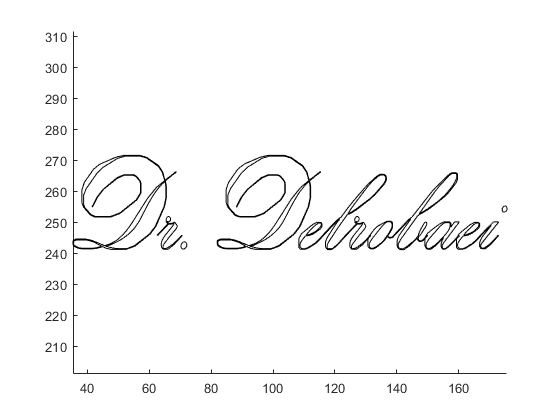

figure();
 dxf=DXFtool("DrDelRobaei.dxf");

here we save the dxf trajectory file in matlab .fig format in case to extract the lines and splines x-y coordinates as follow


    fig_axes = findobj(gcf, 'type', 'axes');
    
%     EE_x=0;
%     EE_y=0.4;
%     scale=0.5;
    
    h = findobj(fig_axes,'Type','line');
    

after retriving data from dxf file we now store this data in "traj" variable

    for i=length(h):-1:1
        traj(i).y=-10^-3*h(i).XData;
        traj(i).x=10^-3*h(i).YData;
    end
 
% modifying data so each field have a same size
    for i=1:length(traj)
    if(length(traj(i).x)~=4)
        traj(i).x=cat(2,traj(i).x,traj(i).x(end)*ones(1,4-length(traj(i).x)));
        traj(i).y=cat(2,traj(i).y,traj(i).y(end)*ones(1,4-length(traj(i).y)));
    end
end


## **Inverse Kinematics of Scara robot**

as it is shown in figure 2 we used the Denavit-Hartenberg method in order to 

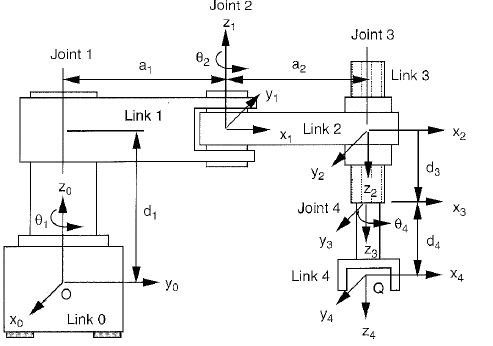

**Figure 2: Scara robot shematic**

calculate the Transform matrix $^{0}T_{4}$ as follow

     
$$^{0}T_{4}=^{0}T_{1} \times^{1}T_{2}\times^{2}T_{3}\times ^{3}T_{4}$$



$$^{0}T_{4}=\left[\begin{array}{cccc}
-\sin \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \cos \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 & -\mathit{a2} \sin \! \left(\theta_{1}+\theta_{2}\right)-\mathit{a1} \sin \! \left(\theta_{1}\right) 
\\
 \cos \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \sin \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 & \mathit{a2} \cos \! \left(\theta_{1}+\theta_{2}\right)+\mathit{a1} \cos \! \left(\theta_{1}\right) 
\\
 0 & 0 & -1 & -\mathit{d4} -\mathit{d} +\mathit{d1}  
\\
 0 & 0 & 0 & 1 
\end{array}\right]
$$


from $^{0}T_{4}
$ we can find the Rotation matrix ($^{0}R_4$) as it is the uper left 3*3 matrix


$$R=\left[\begin{array}{ccc}
-\sin \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \cos \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 
\\
 \cos \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \sin \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 
\\
 0 & 0 & -1 
\end{array}\right]

$$


accordingly  the position vector from base frame can be calculate from $^{0}T_{4}
$ as follow


$$P=\left[\begin{array}{c}
-\mathit{a2} \sin \! \left(\theta_{1}+\theta_{2}\right)-\mathit{a1} \sin \! \left(\theta_{1}\right) 
\\
 \mathit{a2} \cos \! \left(\theta_{1}+\theta_{2}\right)+\mathit{a1} \cos \! \left(\theta_{1}\right) 
\\
 -\mathit{d4} -\mathit{d} +\mathit{d1}  
\end{array}\right]
$$


now that we have the relations between EE_pose:  $[P,R]$ and the joints parameters $[\theta_1,\theta_2,d,\theta_3]$ .for the inverse kinematic alanysis we need to find joint variables in respect to end effector pose which accomplished as follow:

first we suppose that position and orientation of the end-effector is given in the form of transformation matrix as follow


$$^0T_{4}=\left[\begin{array}{cccc}
\mathit{nx}  & \mathit{ox}  & \mathit{ax}  & \mathit{px}  
\\
 \mathit{ny}  & \mathit{oy}  & \mathit{ay}  & \mathit{py}  
\\
 \mathit{nz}  & \mathit{oz}  & \mathit{az}  & \mathit{pz}  
\\
 0 & 0 & 0 & 1 
\end{array}\right]
$$


the set of equations now derived as follow 


$$\left[\begin{array}{cccc}
-\sin \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \cos \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 & -\mathit{a2} \sin \! \left(\theta_{1}+\theta_{2}\right)-\mathit{a1} \sin \! \left(\theta_{1}\right) 
\\
 \cos \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & \sin \! \left(\theta_{1}+\theta_{2}-\theta_{4}\right) & 0 & \mathit{a2} \cos \! \left(\theta_{1}+\theta_{2}\right)+\mathit{a1} \cos \! \left(\theta_{1}\right) 
\\
 0 & 0 & -1 & -\mathit{d4} -d +\mathit{d1}  
\\
 0 & 0 & 0 & 1 
\end{array}\right]
 = 
\left[\begin{array}{cccc}
\mathit{nx}  & \mathit{ox}  & \mathit{ax}  & \mathit{px}  
\\
 \mathit{ny}  & \mathit{oy}  & \mathit{ay}  & \mathit{py}  
\\
 \mathit{nz}  & \mathit{oz}  & \mathit{az}  & \mathit{pz}  
\\
 0 & 0 & 0 & 1 
\end{array}\right]


$$


here the right matrix is known and in the left matrix joint variables are unknown


$$[
-\mathit{a2} \sin \! \left(\theta_{1}+\theta_{2}\right)-\mathit{a1} \sin \! \left(\theta_{1}\right)
 = \mathit{px}, 
\mathit{a2} \cos \! \left(\theta_{1}+\theta_{2}\right)+\mathit{a1} \cos \! \left(\theta_{1}\right)
 = \mathit{py}, -\mathit{d4} -d +\mathit{d1} = \mathit{pz}]


$$



$$d=-\mathit{pz} -\mathit{d4} +\mathit{d1}
$$


for $\theta_1
$,$\theta_2$ we get two solution as follow


$$\cos \! \left(\theta_{2}\right) = 
-\frac{\mathit{a1}^{2}+\mathit{a2}^{2}-\mathit{px}^{2}-\mathit{py}^{2}}{2 \mathit{a1} \mathit{a2}}

$$



$$\theta_{1} = 
-\arctan \! \left(\frac{\cos \! \left(\theta_{2}\right) \mathit{a2} \mathit{px} +\mathit{a2} \mathit{py} \sin \! \left(\theta_{2}\right)+\mathit{a1} \mathit{px}}{-\mathit{a2} \mathit{px} \sin \! \left(\theta_{2}\right)+\mathit{a2} \mathit{py} \cos \! \left(\theta_{2}\right)+\mathit{a1} \mathit{py}}\right)

$$



$$\theta_4=\theta_{1}+\theta_{2}+\arcsin \! \left(\mathit{nx} \right)$$


## Robot WorkSpace

to be sure that the trajectory will fit into robot workspace we need to do a workspace analysis . this analysis will use matlab robotic toolbox

a1=0.25;
a2=0.15;
d1=0.18;
d2=0.15;


Knt_Scara=rigidBodyTree;

body1=rigidBody('Column1');
joint=rigidBodyJoint('fix','fixed');
setFixedTransform(joint,trvec2tform([0 0 0]));
body1.Joint=joint;
addBody(Knt_Scara,body1,'base');

body2=rigidBody('arm1');
joint=rigidBodyJoint('rev1','revolute');
setFixedTransform(joint,trvec2tform([0 0 d1]));
body2.Joint=joint;
addBody(Knt_Scara,body2,'Column1');


body2=rigidBody('arm2');
joint=rigidBodyJoint('rev2','revolute');
setFixedTransform(joint,trvec2tform([a1 0 0]));
body2.Joint=joint;
addBody(Knt_Scara,body2,'arm1');


body2=rigidBody('Column2');
joint=rigidBodyJoint('rev3','revolute');
setFixedTransform(joint,trvec2tform([a2 0 0]));
body2.Joint=joint;
addBody(Knt_Scara,body2,'arm2');


body2=rigidBody('endeffector');
joint=rigidBodyJoint('Fixjoint','Fix');
setFixedTransform(joint,trvec2tform([0 0 -d2]));
body2.Joint=joint;
addBody(Knt_Scara,body2,'Column2');


to generate the workspace figure we can use the following function. but here i used the pre calculated results ,becuase of time consuming simulation 

% ScaraWorkSpace=Scara_WorkSpace(ScaraRobotTree=Knt_Scara);
% hold on 
% PlotTraj(traj);

f=openfig("Scara_WorkSpace.fig");

**Fig3 : scara workspace**

% f2 = figure;
% set(f.Children,'Parent',f2)

as we can see in figure 3, the robot showed in it's two configuration. one in it's minimum radius and second in its maximum radius.

in figure 4 its clear that the given trajectory correctly fit inside robot workspase. so now we can proceed to final stage

% f=openfig("Scara_WorkSpace_Text.fig");
% f3 = figure(4);
% set(f.Children,'Parent',f3)

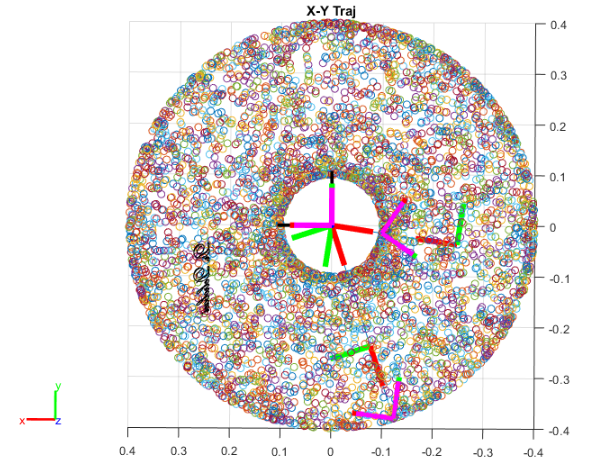

**Fig 4: Robot Workspace and the fitted trajectory **

## Simscape and simulink simulation

here we simulate the Scara robot drawing application in simscape and simulink. 

the robot multibody structure simulated in matlab multibody simscape as shown in fig 5

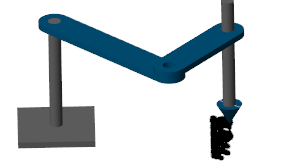

**Fig 5: Scara robot multibody in simscape**

the functional block of the drawing simulation implemented in simulink as shown in fig 6

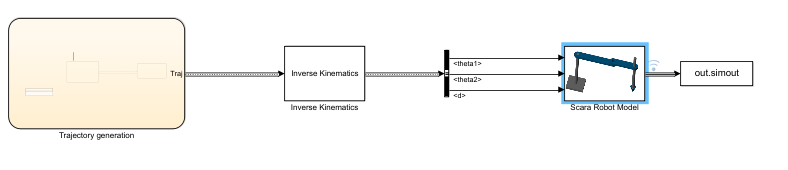

**Fig 6:Simulink Block For Drawing simulation of scara robot**

the final simulation of the robot can be shown in the simulation animation attached to the files

tf_sim=5;


t_samples=length(h)*4;


t.value=linspace(0,tf_sim,t_samples);
t.type="time";



RobotStruct.a1=0.25; %m
RobotStruct.a2=0.15; %m
RobotStruct.d1=0.18;%m
RobotStruct.d4=34.5e-03;%m





x.type="Trans";
x.value= [traj(1).x,traj(1).x(end)*ones(1,length(t.value)-length(traj(1).x))];
x.name="x";

y.type="Trans";
y.value= [traj(1).y,traj(1).y(end)*ones(1,length(t.value)-length(traj(1).y))];
y.name="y";

z.type="Trans";
z.name="z";
z.value=zeros(1,length(t.value));



Trajectory={x,y,z,t};

trajj=traj;
EE_Pose_forSim=TaskSpace(Trajectory);

open('Scara_simulink');
out=sim('Scara_simulink');
    
EE_Pose_bus = Simulink.Bus.createObject('Scara_simulink','Scara_simulink/TaskSpace/Bus Creator');
EE_Pose_simscape_bus = Simulink.Bus.createObject('Scara_simulink','Scara_simulink/Scara Robot Model/Bus Creator');

% delete('BusObjects.m');
% Simulink.Bus.save('BusObjects');